**The Tabular value-fucntion methods on the cart and pole system**

Consider the cart-and-pole system here depicted:

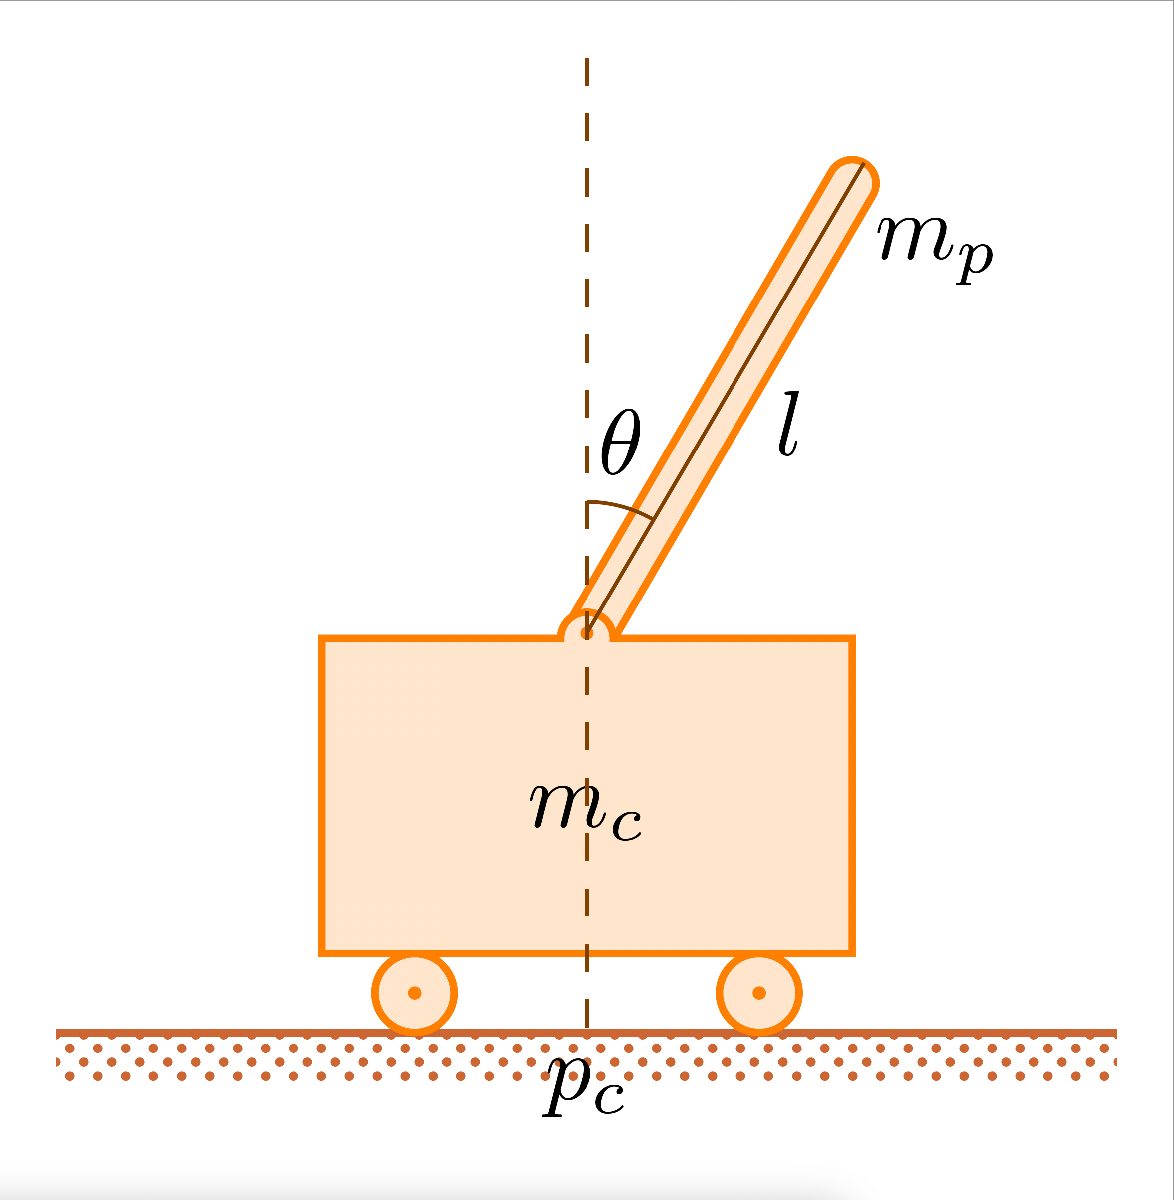

whose dynamics follows the following equations:


$$\ddot{\theta}=\frac{g \sin(\theta)\,+\,\cos(\theta) \left[ \frac{-F\,-\,m_p\,l\,\dot{\theta}^2 \sin \left(\theta\right)\,+\,\mu_c\,\text{sgn}\left(\dot{p}_c\right)}{m_c\,+\,m_p}\right]-\frac{\mu_p\dot{\theta}}{m_p\,l}}{l\,\left[\frac{4}{3}-\frac{m_p\,cos^2\left(\theta\right)}{m_c\,+\,m_p}\right]}$$
   


$$(*)$$



$$  \ddot{p}_c=\frac{F\,+\,m_p\,l\,\left[\dot{\theta}^2\,\sin\left(\theta\right)\,-\,\ddot{\theta}\,\cos(\theta)\right]}{m_c\,+\,m_p}$$


where $g = 9.8\,\text{m/sec}$ is the gravitational acceleration, $m_c = 1\,\text{kg}$ is the cart mass, $m_p = 0.1\,\text{kg}$ is the pole mass, $l = 0.5\,\text{m}$ is the half-pole length, $\mu_p = 0.000002$ is the pole on cart friction coefficient.

% Cleaning the workspace

close all
clear
clc

1.Given the $$\mathcal{X}$$set, select centers and standard deviation of RBFs and create a code that given a state $x$ returns $\phi\left(x,\cdot\right)$

% Define the RBF centers and standard deviation
% Define the ranges for each state variable
position_range = linspace(-3, 3, 7);
speed_range = linspace(-2, 2, 5);
angle_range = linspace(deg2rad(-15), deg2rad(15), 10);
angular_speed_range = linspace(-1, 1, 3);

% Define the RBF centers
[grid1, grid2, grid3, grid4] = ndgrid(position_range, speed_range, angle_range, angular_speed_range);
rbf_centers = [grid1(:), grid2(:), grid3(:), grid4(:)];

% Define the standard deviation of the RBFs
rbf_std_dev = [mean(diff(position_range)), mean(diff(speed_range)), mean(diff(angle_range)), mean(diff(angular_speed_range))];

Here is the function that give a state $x$ returns $\phi\left(x,\cdot\right)$

2. Create a code that applies Q-Learning algorithm with function approximation

uplim = [ 5;
          3
          deg2rad(15);
          3];

lowlim = -1 * uplim;

max_steps = 250;

g = 9.8;
mc = 1;
mp = 0.1;
l = 0.5;
mu_p = 2e-6;

Ts = 0.02;
t_zero = 0;

total_episodes = 5000;
learning_rate = 0.1;           % Alpha
gamma = 0.95;     

epsilon = 1.0;          % This choice ensure high exploration in the first episodes
max_epsilon = 1.0;     
min_epsilon = 0.01;     % This guarantees that also in the last episodes there is some
                        % exploration, not only exploitation
decay_rate = 0.001;     % I want to ensure high exploration during the first episodes

rewards = zeros(1, total_episodes);

ep_check = 250;

% Initialize the weights for the RBFs
% weights = zeros(size(rbf_centers, 1), 2);

**IMPORTANT : **The code in the above line is used only if it's the first run or if the file "weights.mat" does not exist

load weights.mat

% Loop over each episode
for episode = 1:total_episodes

    x0_rand = get_initState();
    
    total_rewards = 0;
    
    % Loop over each step in one episode
    for step = 1:max_steps

        exp_exp_tradeoff = rand();

        % If this number is greater than epsilon we will do exploitation 
        if exp_exp_tradeoff > epsilon
            [~, bool_F] = max(weights' * rbf(x0_rand, rbf_centers, rbf_std_dev));
        % Else doing we do a random choice,resulting in more exploration
        else
            bool_F = randi([1,2]);
        end
        
        % Convert action into force
        if bool_F == 2
            F = 10;
        else
            F = -10;
        end

        % Simulation
        t1 = t_zero + Ts;
        t_sim = [t_zero, t1];
        [t, x] = ode45(@(t,x)cart_pend_for(t, x, g, mp, mc, l, mu_p, F), t_sim, x0_rand);
        new_x0_rand = x(end, :);
        t_zero = t1;
        
        % Check if the new state is terminal
        stop = should_stop(new_x0_rand, lowlim);
        if (stop == 1)
            reward = -100;  % assign penalty
        else
            reward = 1;     % assign reward
        end

        % Update Q(s,a)
        weights(:, bool_F) = weights(:, bool_F) + learning_rate *...
                            (reward + gamma * max(weights' * rbf(new_x0_rand, rbf_centers, rbf_std_dev)) - weights(:, bool_F)' * rbf(x0_rand, rbf_centers, rbf_std_dev)) *...
                             rbf(x0_rand, rbf_centers, rbf_std_dev); %#ok<*SAGROW>
        
        % Update the total rewards
        total_rewards = total_rewards + reward;
        
        % Update the state for iteration
        x0_rand = new_x0_rand;

        % If the system goes out of its boundaries the STOP
        stop = should_stop(new_x0_rand, lowlim);
        if (stop == 1)
            break;
        end
    end
    
    % Reduce epsilon (more exploitation, less exploration)
    epsilon = min_epsilon + (max_epsilon - min_epsilon)*exp(-decay_rate*episode); 
    rewards(episode) = total_rewards;

    if(episode == ep_check)
        ep_check = ep_check + 250;
        episode
    end
end

episode = 250


save("weights.mat", "weights");

sum(rewards)/total_episodes
epsilon

(reward + gamma * max(weights' * rbf(new_x0_rand, rbf_centers, rbf_std_dev)) - weights(:, bool_F)' * rbf(x0_rand, rbf_centers, rbf_std_dev))

ans = -0.5831


plot(rewards); 
legend('Reward over time');
ylim([min(rewards)-10, max(rewards)+10]);

**Simulation of the system (Q-Learning)**

x0_rand = get_initState();

U = [];
x_out = [];
t_out = [];
t_zero = 0;

for step = 1:max_steps
    [~, bool_F] = max(weights' * rbf(x0_rand, rbf_centers, rbf_std_dev));

    if bool_F == 2
        F = 10;
    else
        F = -10;
    end
    
    U = [U, F]; %#ok<*AGROW>

    t1 = t_zero + Ts;
    t_sim = [t_zero, t1];
    [t, x] = ode45(@(t,x)cart_pend_for(t, x, g, mp, mc, l, mu_p, F), t_sim, x0_rand);
    x_out = [x_out; x(end, :)];
    t_out = [t_out, t(end)];
    new_x0_rand = x(end, :);
    t_zero = t1;

    x0_rand = new_x0_rand;

    stop = should_stop(new_x0_rand, lowlim);
    if (stop == 1)
        break;
    end
end

Plot of the simulation

close all
subplot(2,2,1);
plot(t_out, x_out(:,1));
hold on
yline(5, 'r');
yline(-5, 'r');
hold off
xlim([0, 5]);
ylim([-6, 6]);
xlabel("$sec$", Interpreter="latex");
ylabel("$m$", Rotation=90, Interpreter="latex");
grid on
title("Cart position");

subplot(2,2,2);
plot(t_out, x_out(:,2));
grid on
xlim([0, 5]);
xlabel("$sec$", Interpreter="latex");
ylabel("$m/s$", Rotation=90, Interpreter="latex");
title("Cart speed");

subplot(2,2,3);
plot(t_out, x_out(:,3));
hold on;
yline(deg2rad(15), 'r');
yline(deg2rad(-15), 'r');
yline(deg2rad(10), 'g');
yline(deg2rad(-10), 'g');
hold off;
grid on;
xlim([0, 5]);
ylim([deg2rad(-16), deg2rad(16)]);
xlabel("$sec$", Interpreter="latex");
ylabel("$rad$", Rotation=90, Interpreter="latex");
legend("$\theta$", "Terminal Bounds","", "Starting Bounds", Interpreter="latex", location='best');
title("Pole angular position");

subplot(2,2,4);
plot(t_out, x_out(:,4));
grid on
xlim([0, 5]);
xlabel("$sec$", Interpreter="latex");
ylabel("$rad/s$", Rotation=90, Interpreter="latex");
title("Pole angular speed");

close all
plot(t_out, U);
grid on;
ylim([-11, 11]);
xlabel("$sec$", Interpreter="latex");
ylabel("$Newton$", Rotation=90, Interpreter="latex");
title("Force");

Animation of the system

close all
animate_cartpole(t_out, x_out);

3. Copy and paste your Q-learning algorithm with function approximation and apply the changes needed to convert it into a SARSA algorithm with function approximation 

total_episodes = 5000;
learning_rate = 0.1;           % Alpha
gamma = 0.95;     

epsilon = 1.0;          % This choice ensure high exploration in the first episodes
max_epsilon = 1.0;     
min_epsilon = 0.01;     % This guarantees that also in the last episodes there is some
                        % exploration, not only exploitation
decay_rate = 0.001;     % I want to ensure high exploration during the first episodes

num_action = 2; % +10 or -10 N

rewards = zeros(1, total_episodes);
t_zero = 0;

ep_check = 250;

% Initialize the weights for the RBFs
% weights_sarsa = zeros(size(rbf_centers, 1), 2);

**IMPORTANT : **The code in the above line is used only if it's the first run or if the file "weights.mat" does not exist

load weights_sarsa.mat

% Loop over each episode
for episode = 1:total_episodes

    x0_rand = get_initState();
    
    total_rewards = 0;
    
    % Loop over each step in one episode
    for step = 1:max_steps

        exp_exp_tradeoff = rand();

        % If this number is greater than epsilon we will do exploitation 
        if exp_exp_tradeoff > epsilon
            [~, bool_F] = max(weights_sarsa' * rbf(x0_rand, rbf_centers, rbf_std_dev));
        % Else doing we do a random choice,resulting in more exploration
        else
            bool_F = randi([1,2]);
        end
        
        % Convert action into force
        if bool_F == 2
            F = 10;
        else
            F = -10;
        end

        % Simulation
        t1 = t_zero + Ts;
        t_sim = [t_zero, t1];
        [t, x] = ode45(@(t,x)cart_pend_for(t, x, g, mp, mc, l, mu_p, F), t_sim, x0_rand);
        new_x0_rand = x(end, :);
        t_zero = t1;
        
        % Check if the new state is terminal
        stop = should_stop(new_x0_rand, lowlim);
        if (stop == 1)
            reward = -100;  % assign penalty
        else
            reward = 1;     % assign reward
        end

        % If this number is greater than epsilon we will do exploitation 
        if exp_exp_tradeoff > epsilon
            [~, new_bool_F] = max(weights_sarsa' * rbf(x0_rand, rbf_centers, rbf_std_dev));
        % Else doing we do a random choice,resulting in more exploration
        else
            new_bool_F = randi([1,2]);
        end

        % Update Q(s,a)
        weights_sarsa(:, bool_F) = weights_sarsa(:, bool_F) + learning_rate *...
                                  (reward + gamma * weights_sarsa(:, new_bool_F)' * rbf(new_x0_rand, rbf_centers, rbf_std_dev) - weights_sarsa(:, bool_F)' * rbf(x0_rand, rbf_centers, rbf_std_dev)) *...
                                   rbf(x0_rand, rbf_centers, rbf_std_dev);

        
        % Update the total rewards
        total_rewards = total_rewards + reward;
        
        % Update the state for iteration
        x0_rand = new_x0_rand;
        bool_F = new_bool_F;

        % If the system goes out of its boundaries the STOP
        stop = should_stop(new_x0_rand, lowlim);
        if (stop == 1)
            break;
        end
    end
    
    % Reduce epsilon (more exploitation, less exploration)
    epsilon = min_epsilon + (max_epsilon - min_epsilon)*exp(-decay_rate*episode); 
    rewards(episode) = total_rewards;

    if(episode == ep_check)
        ep_check = ep_check + 250;
        episode
    end
end

save("weights_sarsa.mat", "weights_sarsa");

sum(rewards)/total_episodes
epsilon

plot(rewards); 
legend('Reward over time');
ylim([min(rewards)-10, max(rewards)+10]);

**Simulation of the system (SARSA)**

x0_rand = get_initState();

U = [];
x_out = [];
t_out = [];
t_zero = 0;

for step = 1:max_steps
    [~, bool_F] = max(weights_sarsa' * rbf(x0_rand, rbf_centers, rbf_std_dev));

    if bool_F == 2
        F = 10;
    else
        F = -10;
    end
    
    U = [U, F]; %#ok<*AGROW>

    t1 = t_zero + Ts;
    t_sim = [t_zero, t1];
    [t, x] = ode45(@(t,x)cart_pend_for(t, x, g, mp, mc, l, mu_p, F), t_sim, x0_rand);
    x_out = [x_out; x(end, :)];
    t_out = [t_out, t(end)];
    new_x0_rand = x(end, :);
    t_zero = t1;

    x0_rand = new_x0_rand;

    stop = should_stop(new_x0_rand, lowlim);
    if (stop == 1)
        break;
    end
end

Plot of the simulation

close all
subplot(2,2,1);
plot(t_out, x_out(:,1));
hold on
yline(5, 'r');
yline(-5, 'r');
hold off
xlim([0, 5]);
ylim([-6, 6]);
xlabel("$sec$", Interpreter="latex");
ylabel("$m$", Rotation=90, Interpreter="latex");
grid on
title("Cart position");

subplot(2,2,2);
plot(t_out, x_out(:,2));
grid on
xlim([0, 5]);
xlabel("$sec$", Interpreter="latex");
ylabel("$m/s$", Rotation=90, Interpreter="latex");
title("Cart speed");

subplot(2,2,3);
plot(t_out, x_out(:,3));
hold on;
yline(deg2rad(15), 'r');
yline(deg2rad(-15), 'r');
yline(deg2rad(10), 'g');
yline(deg2rad(-10), 'g');
hold off;
grid on;
xlim([0, 5]);
ylim([deg2rad(-16), deg2rad(16)]);
xlabel("$sec$", Interpreter="latex");
ylabel("$rad$", Rotation=90, Interpreter="latex");
legend("$\theta$", "Terminal Bounds","", "Starting Bounds", Interpreter="latex", location='best');
title("Pole angular position");

subplot(2,2,4);
plot(t_out, x_out(:,4));
grid on
xlim([0, 5]);
xlabel("$sec$", Interpreter="latex");
ylabel("$rad/s$", Rotation=90, Interpreter="latex");
title("Pole angular speed");

close all
plot(t_out, U);
grid on;
ylim([-11, 11]);
xlabel("$sec$", Interpreter="latex");
ylabel("$Newton$", Rotation=90, Interpreter="latex");
title("Force");

Animation of the system

close all
animate_cartpole(t_out, x_out);

function dxdt = cart_pend_for(t, x, g, mp, mc, l, mu_p, U) %#ok<*INUSD>

  dxdt = zeros(4,1);

  dxdt(1) = x(2);
  dxdt(2) = (U+mp*l*((x(4)^2)*sin(x(3))-((g*sin(x(3))+ cos(x(3))*((-U-mp*l*(x(4)^2)*sin(x(3)))/(mc+mp))-((mu_p*x(4))/(mp*l)))/(l*((4/3)-((mp*cos(x(3))^2)/(mc+mp)))))*cos(x(3))))/(mc+mp);
  dxdt(3) = x(4);
  dxdt(4) = (g*sin(x(3))+ cos(x(3))*((-U-mp*l*(x(4)^2)*sin(x(3)))/(mc+mp))-((mu_p*x(4))/(mp*l)))/(l*((4/3)-((mp*cos(x(3))^2)/(mc+mp))));

end

function stop = should_stop(dstate, lowBounds)
    if (dstate(1) <= lowBounds(1) || dstate(1) >= -1*lowBounds(1)) ||...
       (dstate(3) <= lowBounds(3) || dstate(3) >= -1*lowBounds(3))
        stop = 1;
    else
        stop = 0;
    end
end

function initState = get_initState()
    %initState = [0, 0, deg2rad(randi([-10, 10])), 0];
    initState = [0, randi([-1, +1]), deg2rad(randi([-10, 10])), randi([-1, +1])/10];
end

function y = rbf(x, centers, std_dev)
    % Initialize the output vector
    y = zeros(size(centers, 1), 1);
    
    % Calculate the RBFs for each center
    for i = 1:size(centers, 1)
        y(i) = exp(-sum(((x - centers(i, :))./std_dev).^2)/2);
    end
end

function animate_cartpole(t, states)
    % Parameters for drawing
    cart_width = 1.0;
    cart_height = 0.5;
    pole_length = 2.0;

    figure;

    for i = 1:length(t)
        % Clear the figure
        clf;

        x = states(i, 1);  % Cart position
        theta = states(i, 3);  % Pole angle

        % Compute the pole's coordinates
        pole_x = x + pole_length * sin(theta);
        pole_y = cart_height / 2 + pole_length * cos(theta);

        % Cart
        rectangle('Position', [x - cart_width / 2, 0, cart_width, cart_height], 'FaceColor', [0, 0, 1]);

        % Pole
        line([x, pole_x], [cart_height / 2, pole_y], 'LineWidth', 2, 'Color', [0, 0, 0]);

        % Ground
        line([-10, 10], [0, 0], 'Color', [0, 1, 0]);


        xlim([-5, +5]);
        ylim([-pole_length - 1, pole_length + 1]);

        pause(0.01);
    end
end